# Signal after MAX2771

%rawdata = randi([0 1], [1 50e3]); 
rawdata = [1 0 1 1 0 1];
%rawdata = [1 0 1 0 1 1 0 1 1 1 1 0 1 0 1 1 0 1 1 1 1 0 1 0 1 1 0 1 1 1 1 0 1 0 1 1 0 1 1 1 1 0 1 0 1 1 0 1 1 1];

%fd      = 50;               % Data frequency
%fca     = 1.023e6;          % C/A code frequency
fd      = 50;               % Data frequency
fca     = 1.023e6;          % C/A code frequency
fc      = fca*20;        % Carrier frequency (Adjusted to not overload RAM)
%fc      = 1575.42e6;        % Carrier frequency
fs      = 20*fc;
sv_id   = 1;                % Satellite Vehicle ID
n       = 1;                % BPSK(1) fc = n*1.023e6; %code rate BPSK(n) spreading code rate n*1.023 MHz
codeLength = round(1023/n); 

fdoppler = [1010, 3425, -280,0];

%Rsignal = 2*Received(rawdata,fd,fca,fc,fs,fdoppler(1),1,1,0);
   
Rsignal = 2*(.2*Received(rawdata,fd,fca,fc,fs,fdoppler(1),1,1,0) + ...
           .2*Received(rawdata,fd,fca,fc,fs,fdoppler(2),8,1,30) + ...
           .2*Received(rawdata,fd,fca,fc,fs,fdoppler(3),20,1,834) + ...
           .2*Received(rawdata,fd,fca,fc,fs,fdoppler(4),12,1,514) + ...
           .2*Received(rawdata,fd,fca,fc,fs,-2180,28,1,230));
          

[I,Q, clk] = MAX2771(Rsignal, fc, fs, fs/(fc), true);
[In,Qn, clkn] = MAX2771(awgn(Rsignal,-20), fc, fs, fs/(fc), true);
[In25,Qn25, clkn25] = MAX2771(awgn(Rsignal,-25), fc, fs, fs/(fc), true);
[In30,Qn30, clkn30] = MAX2771(awgn(Rsignal,-30), fc, fs, fs/(fc), true);

% take n miliseconds
nms = 1;
Acquisition_len = nms*(clk/(20*fd));

## MAX2771 Signal

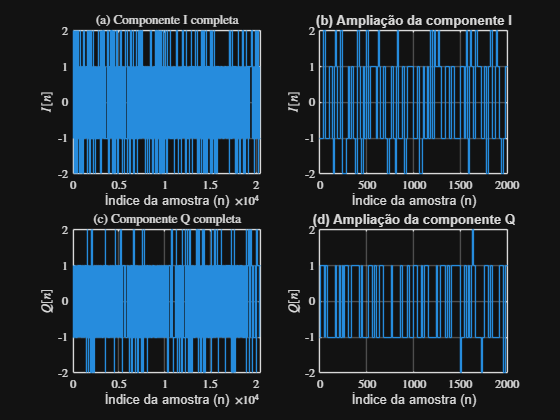

figure('Name', 'Sinais I e Q');
set(groot,'defaultTextInterpreter','latex');
set(groot,'defaultAxesTickLabelInterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
% Sinal completo
subplot(2,2,1)
stairs(I(1:Acquisition_len))
grid on
xlabel('Índice da amostra (n)')
ylabel('$I[n]$')
title('(a) Componente I completa')

% Zoom
subplot(2,2,2)
idx = 1:2000;
stairs(I(idx))
grid on
xlabel('Índice da amostra (n)')
ylabel('$I[n]$')
title('(b) Ampliação da componente I')

% Sinal completo
subplot(2,2,3)
stairs(Q(1:Acquisition_len))
grid on
xlabel('Índice da amostra (n)')
ylabel('$Q[n]$')
title('(c) Componente Q completa')

% Zoom
subplot(2,2,4)
stairs(Q(idx))
grid on
xlabel('Índice da amostra (n)')
ylabel('$Q[n]$')
title('(d) Ampliação da componente Q')

exportgraphics(gcf,'Sinais I e Q.png','Resolution',300);

## MAX2771 Signal with noise

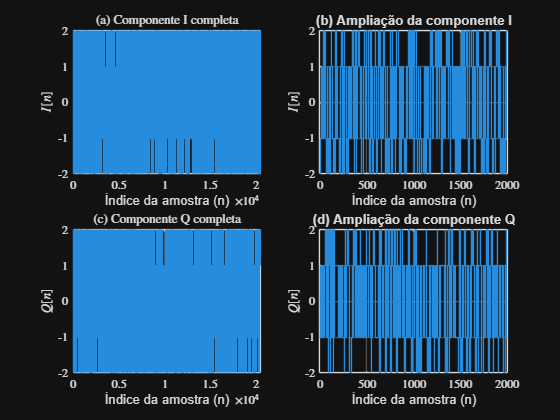

figure('Name', 'Sinais I e Q com ruído AWGN');
% Sinal completo
subplot(2,2,1)
stairs(In(1:Acquisition_len))
grid on
xlabel('Índice da amostra (n)')
ylabel('$I[n]$')
title('(a) Componente I completa')

% Zoom
subplot(2,2,2)
idx = 1:2000;
stairs(In(idx))
grid on
xlabel('Índice da amostra (n)')
ylabel('$I[n]$')
title('(b) Ampliação da componente I')

% Sinal completo
subplot(2,2,3)
stairs(Qn(1:Acquisition_len))
grid on
xlabel('Índice da amostra (n)')
ylabel('$Q[n]$')
title('(c) Componente Q completa')

% Zoom
subplot(2,2,4)
stairs(Qn(idx))
grid on
xlabel('Índice da amostra (n)')
ylabel('$Q[n]$')
title('(d) Ampliação da componente Q')

exportgraphics(gcf,'Sinais I e Q com ruído AWGN.png','Resolution',300);

## Acquisition search

% Search Parameters
fdoppler_step = 100;
doppler_search = 10e3;
w_search = -doppler_search/2:fdoppler_step:doppler_search/2;

% take n miliseconds
nms = 1;
Acquisition_len = nms*(clk/(20*fd));
%Result = Acquisition(I,Q,Acquisition_len,codeLength,nms,doppler_search,fdoppler_step,clk);

I_acquisition = I(1:Acquisition_len);
Q_acquisition = Q(1:Acquisition_len);
IQ = I_acquisition + 1i*Q_acquisition;


%[Max_Corr,index] = Acquisition_search(codeLength,nms,doppler_search,fdoppler_step,clk,IQ);

for SV = 1:32
    % Generate gold code
    gc = data_mapper(gold_code_L1(codeLength,SV));
    gc = upsampler(gc,4);
    gc = expand(gc,nms);
    
    w = 1;
    for w_doppler = -doppler_search/2:fdoppler_step:doppler_search/2
        doppler_wave = exp(1i*2*pi*w_doppler*(0:length(IQ)-1)/(clk*nms)); % O misturador deve ser complexo de forma a eliminar o efeito doppler
        IQ_fft = fft(downsampler(IQ.*doppler_wave,5,2));
        GC = fft(gc);
        Correlation(SV,w,:) = abs(ifft(IQ_fft.*conj(GC))).^2;
        [Max_Corr(SV,w), index(SV,w)] = max(Correlation(SV,w,:));
        w = w + 1;
    end
end

[Corr_Mag, wd] = max(Max_Corr,[],2);
sv = find(Corr_Mag > 1e6);
wd = wd(sv);
W_ = -doppler_search/2 + fdoppler_step*(wd-1);
chips = 0;
for n = 1:length(sv)
    chips(n) = round(index(sv(n),wd(n))/4);
end

Result = sortrows([sv,W_,chips']); %Fim da aquisição

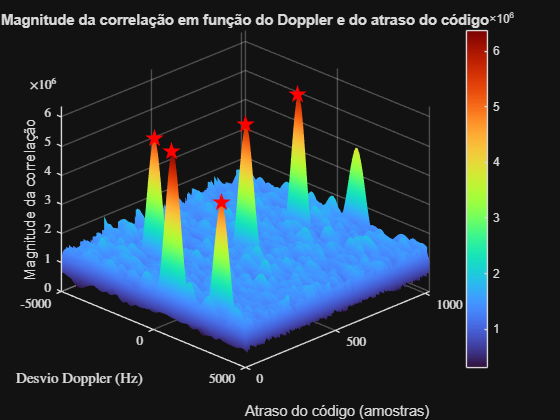

Plot_result = reshape(sum(Correlation,1), [101 size(GC,2)]);
chip_data = ones(101,1).*(0:1/4/nms:1023-1/4/nms);
w_plot = ones(size(GC)).*w_search';

figure('Name', 'Aquisicao1');

surf(w_plot, chip_data, Plot_result, ...
    'EdgeColor','none');

shading interp
colormap turbo
colorbar

xlabel('Desvio Doppler (Hz)')
ylabel('Atraso do código (amostras)')
zlabel('Magnitude da correlação')

title('Magnitude da correlação em função do Doppler e do atraso do código')

view(45,30)
grid on

maxVal = max(Plot_result(wdn, indexn(svn,wdn)),[],2);
fd_plot = Resultn(:,2);
tau = Resultn(:,3);

hold on
plot3(fd_plot, tau, maxVal,...
    'rp','MarkerSize',12,'MarkerFaceColor','r')

I_acquisitionn = In(1:Acquisition_len);
Q_acquisitionn = Qn(1:Acquisition_len);
IQn = I_acquisitionn + 1i*Q_acquisitionn;


%[Max_Corr,index] = Acquisition_search(codeLength,nms,doppler_search,fdoppler_step,clk,IQ);


for SV = 1:32
    % Generate gold code
    gc = data_mapper(gold_code_L1(codeLength,SV));
    gc = upsampler(gc,4);
    gc = expand(gc,nms);
    
    wn = 1;
    for w_doppler = -doppler_search/2:fdoppler_step:doppler_search/2
        doppler_wave = exp(1i*2*pi*w_doppler*(0:length(IQn)-1)/(clk*nms)); % O misturador deve ser complexo de forma a eliminar o efeito doppler
        IQ_fftn = fft(downsampler(IQn.*doppler_wave,5,2));
        GC = fft(gc);
        Correlation(SV,wn,:) = abs(ifft(IQ_fftn.*conj(GC))).^2;
        [Max_Corrn(SV,wn), indexn(SV,wn)] = max(Correlation(SV,wn,:));
        wn = wn + 1;
    end
end


[Corr_Magn, wdn] = max(Max_Corrn,[],2);
svn = find(Corr_Magn > 1e6);
wdn = wdn(svn);
W_n = -doppler_search/2 + fdoppler_step*(wdn-1);
chipsn = 0;
for n = 1:length(svn)
    chipsn(n) = round(indexn(svn(n),wdn(n))/4);
end

Resultn = sortrows([svn,W_n,chipsn']); %Fim da aquisição

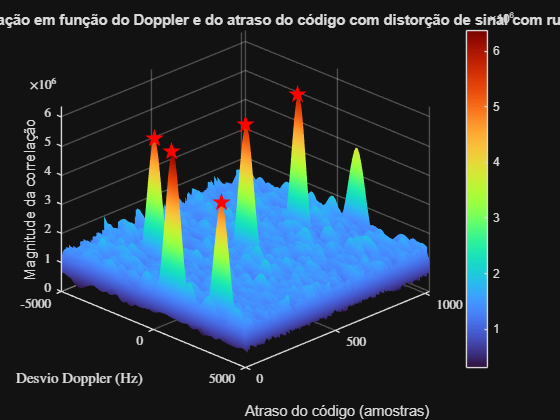

Plot_resultn = reshape(sum(Correlation,1), [101 size(GC,2)]);
chip_data = ones(101,1).*(0:1/4/nms:1023-1/4/nms);
w_plot = ones(size(GC)).*w_search';

figure('Name', 'Aquisicao2');

surf(w_plot, chip_data, Plot_resultn, ...
    'EdgeColor','none');

shading interp
colormap turbo
colorbar

xlabel('Desvio Doppler (Hz)')
ylabel('Atraso do código (amostras)')
zlabel('Magnitude da correlação')

title('Magnitude da correlação em função do Doppler e do atraso do código com distorção de sinal com ruído AWGN')

view(45,30)
grid on

maxValn = max(Plot_resultn(wdn, indexn(svn,wdn)),[],2);
fd_plotn = Resultn(:,2);
taun = Resultn(:,3);

hold on
plot3(fd_plotn, taun, maxValn,...
    'rp','MarkerSize',12,'MarkerFaceColor','r')

# Aquisição com ruído AWGN em -25 dB

I_acquisitionn25 = In25(1:Acquisition_len);
Q_acquisitionn25 = Qn25(1:Acquisition_len);
IQn25 = I_acquisitionn25 + 1i*Q_acquisitionn25;


%[Max_Corr,index] = Acquisition_search(codeLength,nms,doppler_search,fdoppler_step,clk,IQ);


for SV = 1:32
    % Generate gold code
    gc = data_mapper(gold_code_L1(codeLength,SV));
    gc = upsampler(gc,4);
    gc = expand(gc,nms);

    wn = 1;
    for w_doppler = -doppler_search/2:fdoppler_step:doppler_search/2
        doppler_wave = exp(1i*2*pi*w_doppler*(0:length(IQn25)-1)/(clk*nms)); % O misturador deve ser complexo de forma a eliminar o efeito doppler
        IQ_fftn25 = fft(downsampler(IQn25.*doppler_wave,5,2));
        GC = fft(gc);
        Correlation25(SV,wn,:) = abs(ifft(IQ_fftn25.*conj(GC))).^2;
        [Max_Corrn25(SV,wn), indexn25(SV,wn)] = max(Correlation25(SV,wn,:));
        wn = wn + 1;
    end
end


[Corr_Magn25, wdn] = max(Max_Corrn25,[],2);
svn25 = find(Corr_Magn25 > 1e6);
wdn25 = wdn(svn25);
W_n25 = -doppler_search/2 + fdoppler_step*(wdn25-1);
chipsn25 = 0;
for n = 1:length(svn25)
    chipsn25(n) = round(indexn(svn25(n),wdn25(n))/4);
end

Resultn = sortrows([svn25,W_n25,chipsn25']); %Fim da aquisição

Plot_resultn = reshape(sum(Correlation,1), [101 size(GC,2)]);
chip_data = ones(101,1).*(0:1/4/nms:1023-1/4/nms);
w_plot = ones(size(GC)).*w_search';

figure('Name', 'Aquisicao2');

surf(w_plot, chip_data, Plot_resultn, ...
    'EdgeColor','none');

shading interp
colormap turbo
colorbar

xlabel('Desvio Doppler (Hz)')
ylabel('Atraso do código (amostras)')
zlabel('Magnitude da correlação')

title('Magnitude da correlação em função do Doppler e do atraso do código com distorção de sinal com ruído AWGN')

view(45,30)
grid on

maxValn = max(Plot_resultn(wdn, indexn(svn,wdn)),[],2);
fd_plotn = Resultn(:,2);
taun = Resultn(:,3);

hold on
plot3(fd_plotn, taun, maxValn,...
    'rp','MarkerSize',12,'MarkerFaceColor','r')